run('sim_init.mlx')

   USAGE: PLECS('CMD','PARAMETER1','PARAMETER2',...)
     Known commands are: get, set, version, hostid, thermal, scope, checkout


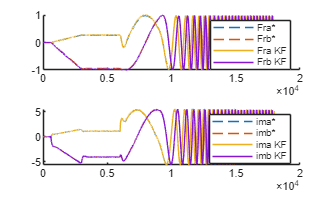

plot_Filtering(KF)

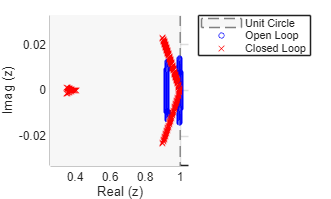

plot_LGR(KF)

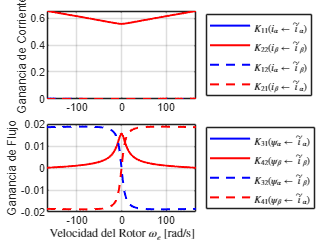

plot_Scheduled_Gains(KF)

function plot_Filtering(KF)
    x = struct();
    x.qi = KF.qi;
    x.qF = KF.qF;
    data = load('KF_TuningData.mat').out';
    do_plot = true;
    KF_simulate(x, data, do_plot);
end

function plot_LGR(KF)
%PLOT_POLE_MAP_FINAL Plots the root locus of the machine and the filter.
%   Displays Open Loop vs Closed Loop poles and the Unit Circle with external legend.

    % Create figure (slightly wider to accommodate external legend)
    figure
    hold on; grid on;

    % --- 1. Draw Unit Circle (Stability Limit) ---
    theta = linspace(0, 2*pi, 200);
    % We save the handle (h_uc) and set the DisplayName for the legend
    h_uc = fill(cos(theta), sin(theta), [0.97 0.97 0.97], ...
        'EdgeColor', [0.5 0.5 0.5], 'LineStyle', '--', ...
        'DisplayName', 'Unit Circle'); 

    % --- 2. Plot Point Clouds ---
    % Open Loop (Blue) - Machine Dynamics
    h_ol = plot(real(KF.ol_poles_list(:)), imag(KF.ol_poles_list(:)), ...
        'bo', 'MarkerSize', 4, 'DisplayName', 'Open Loop');
    
    % Closed Loop (Red) - Filter Dynamics
    h_cl = plot(real(KF.cl_poles_list(:)), imag(KF.cl_poles_list(:)), ...
        'rx', 'MarkerSize', 6, 'DisplayName', 'Closed Loop');

    % --- 3. Smart Zoom (Tight Fit) ---
    all_poles = [KF.cl_poles_list(:); KF.ol_poles_list(:)];
    min_x = min(real(all_poles)); max_x = max(real(all_poles));
    min_y = min(imag(all_poles)); max_y = max(imag(all_poles));
    
    % 15% margin for better visualization
    margin_x = max((max_x - min_x) * 0.15, 0.01); 
    margin_y = max((max_y - min_y) * 0.15, 0.01);
    
    % Set limits, ensuring we don't lose the Unit Circle boundary if close
    xlim([min_x - margin_x, min(1.05, max_x + margin_x)]); 
    ylim([min_y - margin_y, max_y + margin_y]);

    % --- 4. Final Decoration ---
    xlabel('Real (z)');
    ylabel('Imag (z)');
    
    % Legend placed outside the plot area
    legend([h_uc, h_ol, h_cl], 'Location', 'northeastoutside');
    
    hold off;
end

function plot_Scheduled_Gains(KF)
%PLOT_KALMAN_GAINS_DETAILED Grafica los elementos de la matriz de ganancia K.
%   Separa las ganancias de corrección de Corriente y de Flujo.
%   Usa las variables de la estructura KF provista.

    % 1. Extraer Eje X (Velocidad)
    w_axis = KF.we_list;

    % 2. Desempaquetar la Matriz 3D (4x2xSteps)
    % Notación: K_fila_columna -> K_estado_medida
    
    % --- Grupo 1: Corrección de Estados de CORRIENTE (Filas 1 y 2) ---
    % Fila 1 (i_alpha)
    K_ia_ia = squeeze(KF.gain_schedule(1, 1, :)); % De error i_alpha
    K_ia_ib = squeeze(KF.gain_schedule(1, 2, :)); % De error i_beta
    % Fila 2 (i_beta)
    K_ib_ia = squeeze(KF.gain_schedule(2, 1, :)); % De error i_alpha
    K_ib_ib = squeeze(KF.gain_schedule(2, 2, :)); % De error i_beta

    % --- Grupo 2: Corrección de Estados de FLUJO (Filas 3 y 4) ---
    % Fila 3 (psi_alpha)
    K_pa_ia = squeeze(KF.gain_schedule(3, 1, :)); % De error i_alpha
    K_pa_ib = squeeze(KF.gain_schedule(3, 2, :)); % De error i_beta
    % Fila 4 (psi_beta)
    K_pb_ia = squeeze(KF.gain_schedule(4, 1, :)); % De error i_alpha
    K_pb_ib = squeeze(KF.gain_schedule(4, 2, :)); % De error i_beta

    % 3. Configuración de Figura Estilo IEEE
    figure('Name', 'Kalman Gain Schedule', 'Color', 'w', 'Position', [100, 100, 800, 600]);
    t = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

    % --- PLOT SUPERIOR: Ganancias de Corriente ---
    nexttile; hold on; grid on; box on;
    % Términos Directos (ia->ia, ib->ib) -> Líneas Sólidas
    plot(w_axis, K_ia_ia, 'b-', 'LineWidth', 1.5, 'DisplayName', '$K_{11} (i_\alpha \leftarrow \tilde{i}_\alpha)$');
    plot(w_axis, K_ib_ib, 'r-', 'LineWidth', 1.5, 'DisplayName', '$K_{22} (i_\beta \leftarrow \tilde{i}_\beta)$');
    % Términos Cruzados (ia->ib, ib->ia) -> Líneas Punteadas
    plot(w_axis, K_ia_ib, 'b--', 'LineWidth', 1.5, 'DisplayName', '$K_{12} (i_\alpha \leftarrow \tilde{i}_\beta)$');
    plot(w_axis, K_ib_ia, 'r--', 'LineWidth', 1.5, 'DisplayName', '$K_{21} (i_\beta \leftarrow \tilde{i}_\alpha)$');
    
    ylabel('Ganancia de Corriente');
    legend('Location', 'eastoutside', 'Interpreter', 'latex');
    xlim([min(w_axis), max(w_axis)]);

    % --- PLOT INFERIOR: Ganancias de Flujo ---
    nexttile; hold on; grid on; box on;
    % Términos Directos (pa->ia, pb->ib) -> Líneas Sólidas
    plot(w_axis, K_pa_ia, 'b-', 'LineWidth', 1.5, 'DisplayName', '$K_{31} (\psi_\alpha \leftarrow \tilde{i}_\alpha)$');
    plot(w_axis, K_pb_ib, 'r-', 'LineWidth', 1.5, 'DisplayName', '$K_{42} (\psi_\beta \leftarrow \tilde{i}_\beta)$');
    % Términos Cruzados (pa->ib, pb->ia) -> Líneas Punteadas
    plot(w_axis, K_pa_ib, 'b--', 'LineWidth', 1.5, 'DisplayName', '$K_{32} (\psi_\alpha \leftarrow \tilde{i}_\beta)$');
    plot(w_axis, K_pb_ia, 'r--', 'LineWidth', 1.5, 'DisplayName', '$K_{41} (\psi_\beta \leftarrow \tilde{i}_\alpha)$');

    xlabel('Velocidad del Rotor $\omega_e$ [rad/s]', 'Interpreter', 'latex');
    ylabel('Ganancia de Flujo');
    legend('Location', 'eastoutside', 'Interpreter', 'latex');
    xlim([min(w_axis), max(w_axis)]);
end